clear

% 1. Load Data
load('MobileSensorData\50steps.mat'); % Sample with 50 steps (fixed)
lat=Position.latitude;
lon=Position.longitude;
positionDatetime=Position.Timestamp;

Xacc = Acceleration.X;
Yacc = Acceleration.Y;
Zacc = Acceleration.Z;
accelDatetime=Acceleration.Timestamp;

% We use the following to obtain linear time data in seconds from a datetime array
positionTime=timeElapsed(positionDatetime);
accelTime=timeElapsed(accelDatetime);

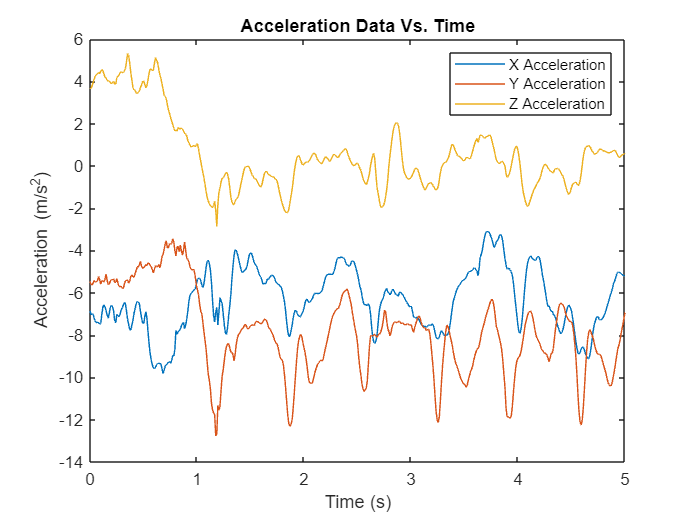

% 2. Plot Data

plot(accelTime,Xacc);
hold on;
plot(accelTime,Yacc); 
plot(accelTime,Zacc);
xlim([0 5])
legend('X Acceleration','Y Acceleration','Z Acceleration');
xlabel('Time (s)')
ylabel('Acceleration (m/s^2)');
title('Acceleration Data Vs. Time');
hold off

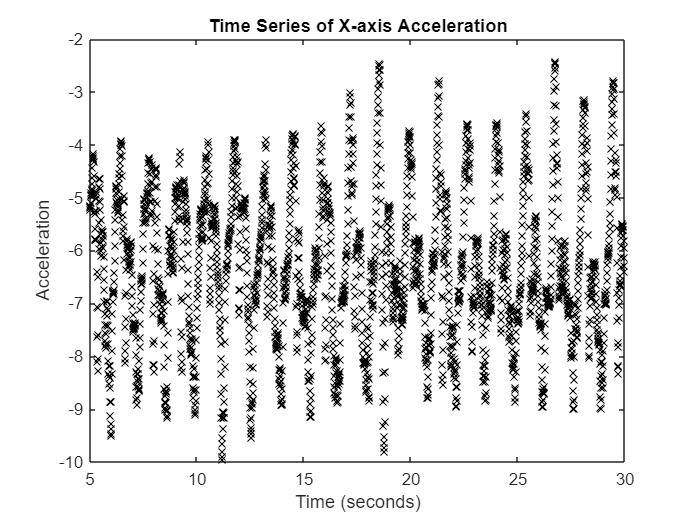

% 3. TODO: Create ML model to compute accurate stride (instead than using
% formulae)

% focus on Zacc
ts = timeseries(Xacc, accelTime);
plot(ts, "kx")
title("Time Series of X-axis Acceleration")
ylabel("Acceleration")
xlim([5 30])


% filter human-introduced bias (to press start&end)
ts_filtered = getsampleusingtime(ts, 5, 30);

% N. steps = 50

% This block is not integrated


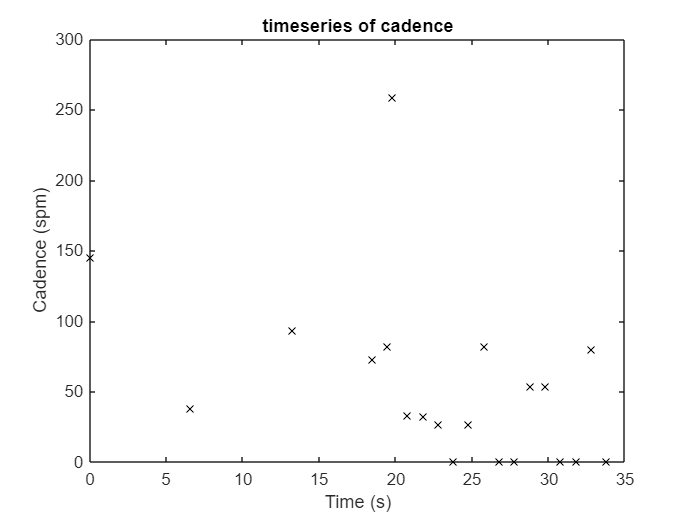

% Temporary solution
earthCirc = 24901;
totaldis = 0;

cadence = zeros(1, size(positionTime, 1));

stride = 2.5; % average feet, consider to replace with sensor data

for i = 1:(length(lat)-1)
    lat1 = lat(i);
    lat2 = lat(i+1);
    lon1 = lon(i);
    lon2 = lon(i+1);

    degDis = distance(lat1, lon1, lat2, lon2);
    dis = (degDis/360)*earthCirc;
    
    % Progressive Distance
    totaldis = totaldis + dis;

    % actual steps
    steps = ((dis*5280)/stride)/3.2808; % convert in meters

    % actual cadence
    if i == 1 
        cadence(i) = 60*steps; % 60 seconds
    else
        cadence(i) = 60*steps / (positionTime(i)-positionTime(i-1));
    end

end

plot(positionTime(1:end), cadence, "kx")
title("timeseries of cadence")
xlabel("Time (s)")
ylabel("Cadence (spm)")